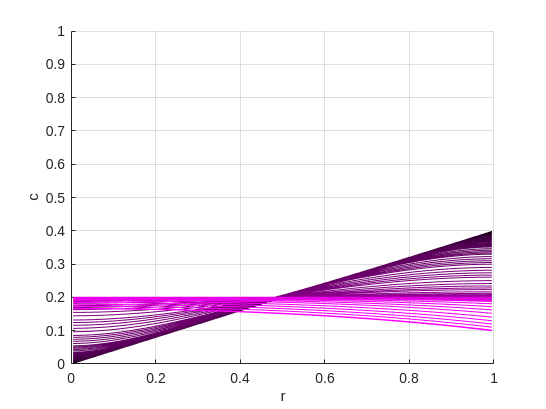

clear all
clf
clc

R = 1;
nbin = 100;    %same as nr-1 in mechanics
dr = R/(nbin);
rbin = linspace(dr/2,R-dr/2,nbin);
redge = linspace(0,R,nbin+1);
ntime = 200;
tstart = 0;
tend = 1000;
%tspan = linspace(tstart,tend,ntime);
%I = 0.5*ones(1,length(tspan));
D0 = 1;
% I = 0;
gamma = 1;
G = 1;
params =[D0 gamma G R nbin];

mass_m = zeros(2*nbin);   %u on edges (except origin), c in bins
mass_m(nbin+1:end,nbin+1:end) = eye(nbin);
options = odeset('Mass',mass_m,'Events',@cEventsFun);

u0 = 0*ones(1,nbin);  %excludes origin


%c0 = 0.5*ones(1,nbin);
c0 = 0.4.*rbin;
w0 = [u0, c0];

[t,w_res] = ode15s(@(t,w) radial_transport_mechanics(t,w,params),[0 30],w0,options);

u_res = w_res(:,1:nbin);
c_res = w_res(:,nbin+1:end);

tsize = size(u_res);

figure()
ylim([0 1])
xlabel('r')
ylabel('c')
for i = 1:tsize(1)
    hold on
    plot(rbin,c_res(i,:),"Color",[i/tsize(1) 0 i/tsize(1)])
end
grid on
hold off

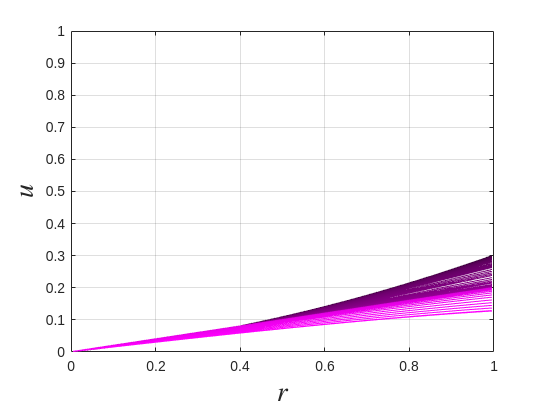


figure()
xlabel('$r$','Interpreter','latex','FontSize',20)
ylabel('$u$','Interpreter','latex','FontSize',20)
ylim([0 1])
for i = 1:tsize(1)
    hold on
    plot(rbin,u_res(i,:),"Color",[i/tsize(1) 0 i/tsize(1)])
end
grid on
box on
hold off

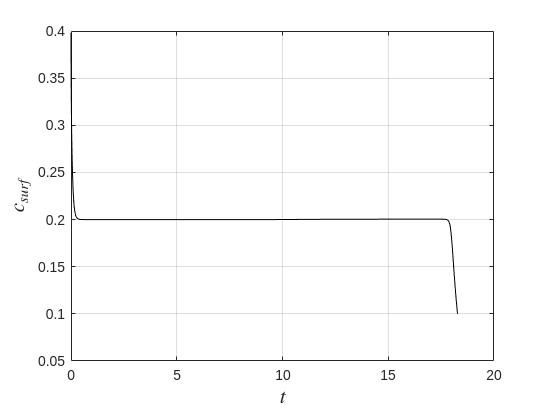


figure()
plot(t,c_res(:,end),'k')
xlabel('$t$','Interpreter','latex', 'FontSize',15)
ylabel('$c_{surf}$','Interpreter','Latex', 'FontSize',15)
grid on
box on


c_init = 0.4;
I=-0.2*(Theta(t,13)-Theta(t,15)-Theta(t,18)+Theta(t,20));
SOC=cumtrapz(t,I);

figure() %dynamic hysteresis
plot(SOC+c_init,c_res(:,end),'k')
xlabel('SOC','Interpreter','latex', 'FontSize',15)
ylabel('$c_{surf}$','Interpreter','latex', 'FontSize',15)
grid on
box on


Functions

function f = radial_transport_mechanics(t, w, params)
D0 = params(1);
gamma = params(2);
G = params(3);
R = params(4);
nbin = params(5);
dr = R/(nbin);

I=-0.2*(Theta(t,13)-Theta(t,15)-Theta(t,18)+Theta(t,20));

r_edge = linspace(0,R,nbin+1)';
r_bin = linspace(dr/2, R-dr/2, nbin)';


f = zeros(length(w),1);
%w = [u(nbin+1),c(nbin)]
u_in = w(1:nbin);
c = w(nbin+1:end);

u1 = [0; u_in];
%Mechanics part
%u(1) = 0;   %boundary condition

e_s = c;

e_rr = (u1(2:end)-u1(1:end-1))/dr;

e_tt = (u1(2:end)+u1(1:end-1))./(2*r_bin);

sigma_rr = zeros(nbin+1,1);  %ghost bin
sigma_rr(1:end-1) = 2*G*(e_rr - e_s) + (e_rr + 2*e_tt - 3*e_s);
sigma_rr(end)= -sigma_rr(length(sigma_rr)-1);  %boundary condition

sigma_tt = 2*G*(e_tt-e_s) + (e_rr + 2*e_tt - 3*e_s);

sigma_rr_edge = (sigma_rr(2:end)+sigma_rr(1:end-1))/2;
sigma_tt_edge = (sigma_tt(2:end)+sigma_tt(1:end-1))/2;
sigma_tt_edge(end+1) = sigma_tt_edge(nbin-1);


f(1:nbin) = (sigma_rr(2:end)-sigma_rr(1:end-1))/dr + (2./r_edge(2:end)).*(sigma_rr_edge - sigma_tt_edge);


sigma_kk = sigma_rr(1:end-1) + 2.*sigma_tt;



%Transport part

if any(c<0)
    disp('BREAK')
end



mu = log(c./(1-c)) - gamma.*sigma_kk;


c_edge = (c(2:end) + c(1:end-1))/2; %interpolates for c on edges


Fr = zeros(nbin+1,1);
Fr(2:end-1) = -D0.*c_edge.*(1-c_edge).*((mu(2:end)-mu(1:end-1))/dr);


Fr(1) = 0;   %Boundary conditions
Fr(end) = I;



%div_flux = ((r_edge(2:end).^2.*(Fr(2:end))) - (r_edge(1:end-1).*Fr(1:end-1)))/dr;
div_flux = (((Fr(2:end))) - (Fr(1:end-1)))/dr;

dcdt = -(1./(r_bin.^2) .* (r_bin.^2.*div_flux));

f(nbin+1:end) = dcdt;


end

function theta = Theta(t,t0)
theta = 0.5*(1+ tanh(10*(t-t0)));
end

Event Function - maybe not needed

function [value, isterminal, direction] = cEventsFun(t,w,params)

value = (w(end)-0.1)*(0.9-w(end));

isterminal = 1;
direction = 0;

end